[y, Fs] = audioread('AudioFile.wav');
t = 0:1/Fs:1;
samples = [1, (1*Fs)+1] 

samples =            1       44101


[y, Fs] = audioread('AudioFile.wav',samples);
y = y(:,1);

%% Time specifications:
% Fs = 1000;                      % samples per second
dt = 1/Fs;                     % seconds per sample
StopTime = 1;                  % seconds
t = (0:dt:StopTime)';
N = length(t)

N = 44101

%% Sine wave:
% Fc = 52;                       % hertz
% x = cos(2*pi*Fc*t);
%% Fourier Transform:
% X = fftshift(fft(x));
Y = fftshift(fft(y));
%% Frequency specifications:
dF = Fs/N;                      % hertz
f = -Fs/2:dF:Fs/2-dF;           % hertz
%% Plot the spectrum:


figure;
subplot (2,1,1)
length(y)

ans = 44101

length(t)

ans = 44101

plot(t, y)
xlabel('Time (in seconds)');
%    title('Magnitude Response');
subplot (2,1,2)
half_f = f(length(f)/2:length(f));

half_Y = (abs(Y)/N);
plot(half_f, half_Y(end/2:end));

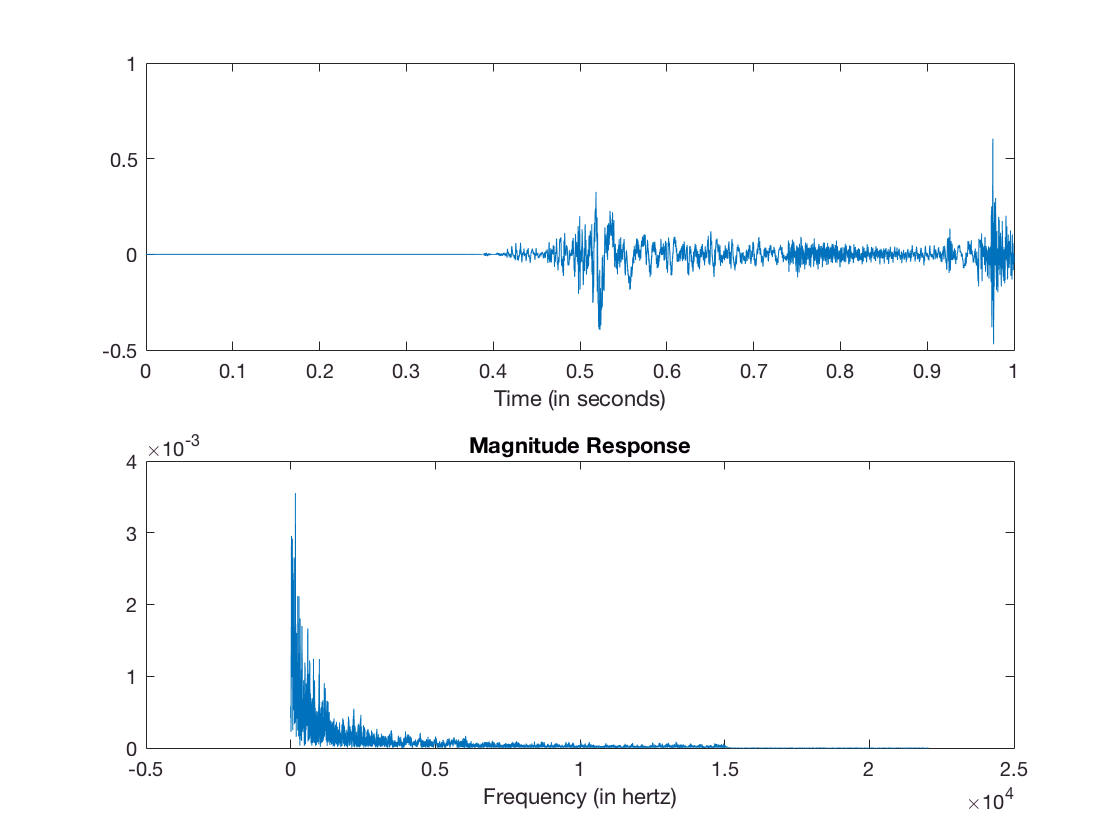

% plot(f, (abs(X)/N))
xlabel('Frequency (in hertz)');
title('Magnitude Response');

dt = 1/Fs;                     % seconds per sample
N = length(t)
Y = fftshift(fft(y));
dF = Fs/N;                      % hertz
f = -Fs/2:dF:Fs/2-dF;           % hertz

L = length(y);
Y = fft(y);
Y = abs(Y/L); % Normalizing FFT
title('signal Y(w) in the time domain');

omega = ((0:length(Y)-1)/length(Y))*fs; %define frequency axis

%% Second Graph, Frequency
subplot(2,1,2)
plot(omega, Y)
title('signal Y(\omega), magnitude')
xlabel(sprintf('t, sampled at the rate of %d', fs));
ylabel('Y(\omega)');
% axis([0 length(Y) 0 max(Y)])